# Projekt 5

## Nastavitev parametrov

% Definicija parametrov
T = 0.01;
N = 300;
N_APRBS = 3000;
amplitude_train = 2.5;
amplitude_test = 2.0;
Th = 0.20;
padding = 100;
dV = 0.05;
c = zeros(2 / dV + 1, 1);

## Statična karaktersitika

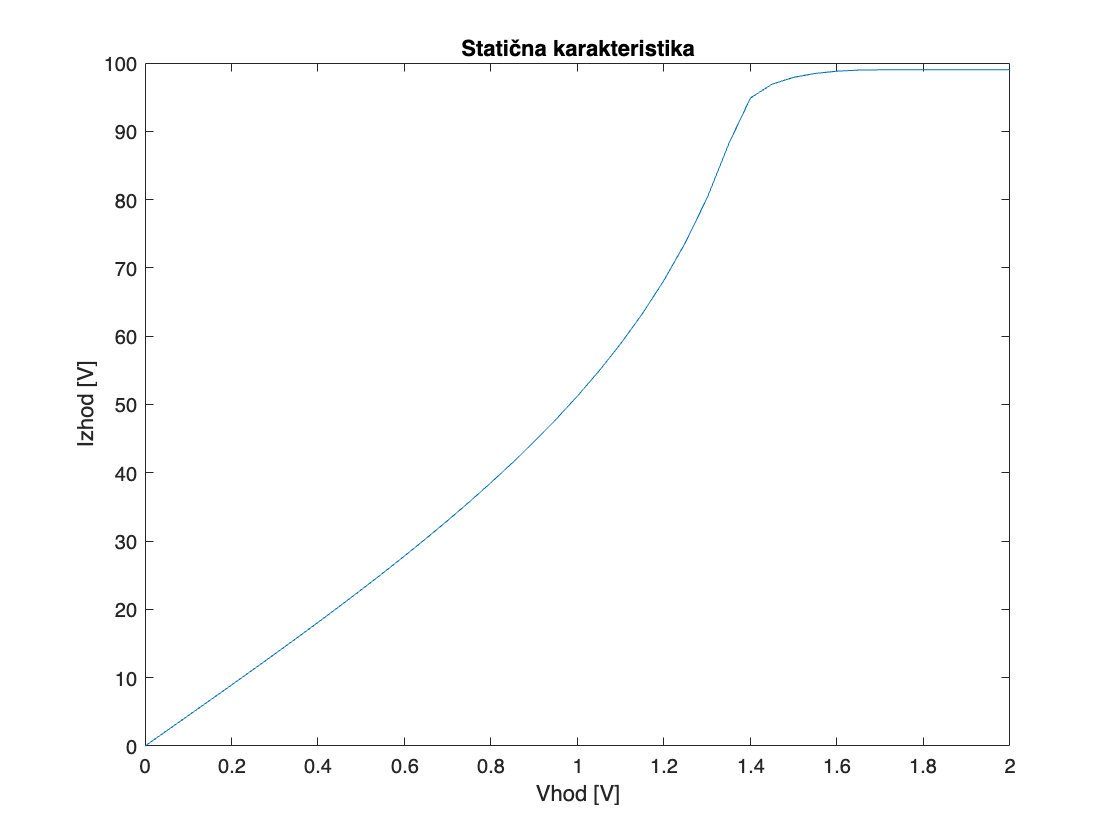

% Zanka za različne vrednosti V
for V = 0:dV:2
    u = ones(N, 1) * V;

    % Inicializacija stanja
    x = [0, 0];

    % Inicializacija izhodnega vektorja
    y = zeros(N, 1);

    % Simulacija helicrana
    for i = 1:N
        % Klic funkcije helicrane
        [fi_, fip_] = helicrane(u(i), x);

        % Posodobitev stanja
        x = [fip_, fi_];

        % Shranjevanje izhoda
        y(i) = fi_;
    end

    % Izračun povprečja izhodnih vrednosti po prehodnem obdobju
    y_m = mean(y(100:end));

    % Shranjevanje rezultata v c
    c(round(V/dV) + 1) = y_m;
end

% Risanje rezultata
figure;
plot(0:dV:2, c);
title("Statična karakteristika");
xlabel("Vhod [V]");
ylabel("Izhod [V]");

## Generiranje in risanje APRBS signala

% Parametri
N = 1000; % Število vzorcev
Th = 5; % Časovna konstanta
T = 0.1; % Čas vzorčenja
amplitude_train = 2.5;
amplitude_test = 2.5;
padding = 100;
N_APRBS = N; % Število APRBS vzorcev

% Generiranje APRBS signala za treniranje
u_train = idinput(N, 'prbs', [0 1 / (Th / T)], [-1 1]);

d_train = diff(u_train);
idx_train = find(d_train) + 1;
idx_train = [1; idx_train];
for ii = 1:length(idx_train) - 1
    u_train(idx_train(ii):idx_train(ii + 1) - 1) = amplitude_train * rand;
end
u_train(idx_train(end):end) = amplitude_train * rand;
u_train = [zeros(padding, 1); u_train];
u_train = u_train - 0.5; % Odštejemo 0.5, da premaknemo signal
% tukaj in pri testu more it vzbujanje v negativ, drugače ga izhodni signal
% serje in pride gre proti 0

% Generiranje APRBS signala za testiranje
u_test = idinput(N, 'prbs', [0 1 / (Th / T)], [-1 1]);

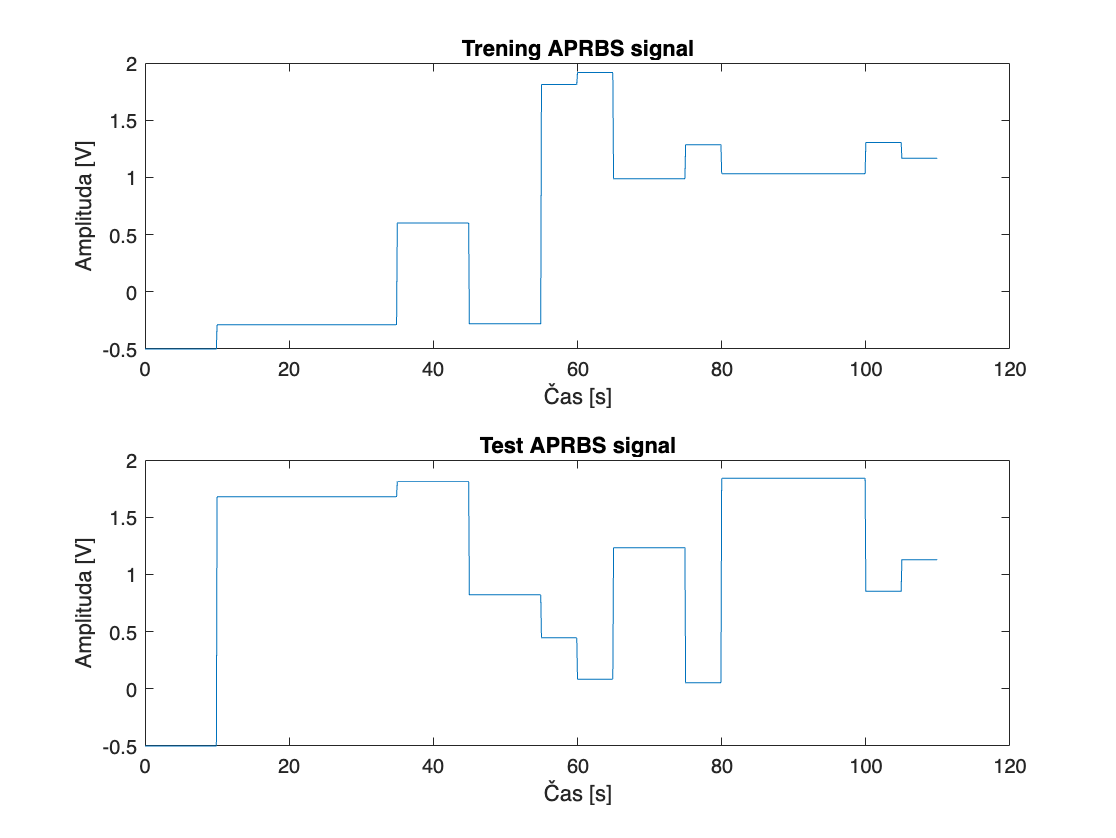

d_test = diff(u_test);
idx_test = find(d_test) + 1;
idx_test = [1; idx_test];
for ii = 1:length(idx_test) - 1
    u_test(idx_test(ii):idx_test(ii + 1) - 1) = amplitude_test * rand;
end
u_test(idx_test(end):end) = amplitude_test * rand;
u_test = [zeros(padding, 1); u_test];
u_test = u_test - 0.5; % Odštejemo 0.5, da premaknemo signal
% tukaj in pri train more it vzbujanje v negativ, drugače ga izhodni signal
% serje in pride gre proti 0

% Časovni vektorji
t_train = (0:length(u_train)-1) * T;
t_test = (0:length(u_test)-1) * T;

% Risanje rezultatov
figure
subplot(2, 1, 1);
plot(t_train, u_train);
title("Trening APRBS signal");
xlabel("Čas [s]");
ylabel("Amplituda [V]");

subplot(2, 1, 2);
plot(t_test, u_test);
title("Test APRBS signal");
xlabel("Čas [s]");
ylabel("Amplituda [V]");

## odziv sistema na vhodni signal

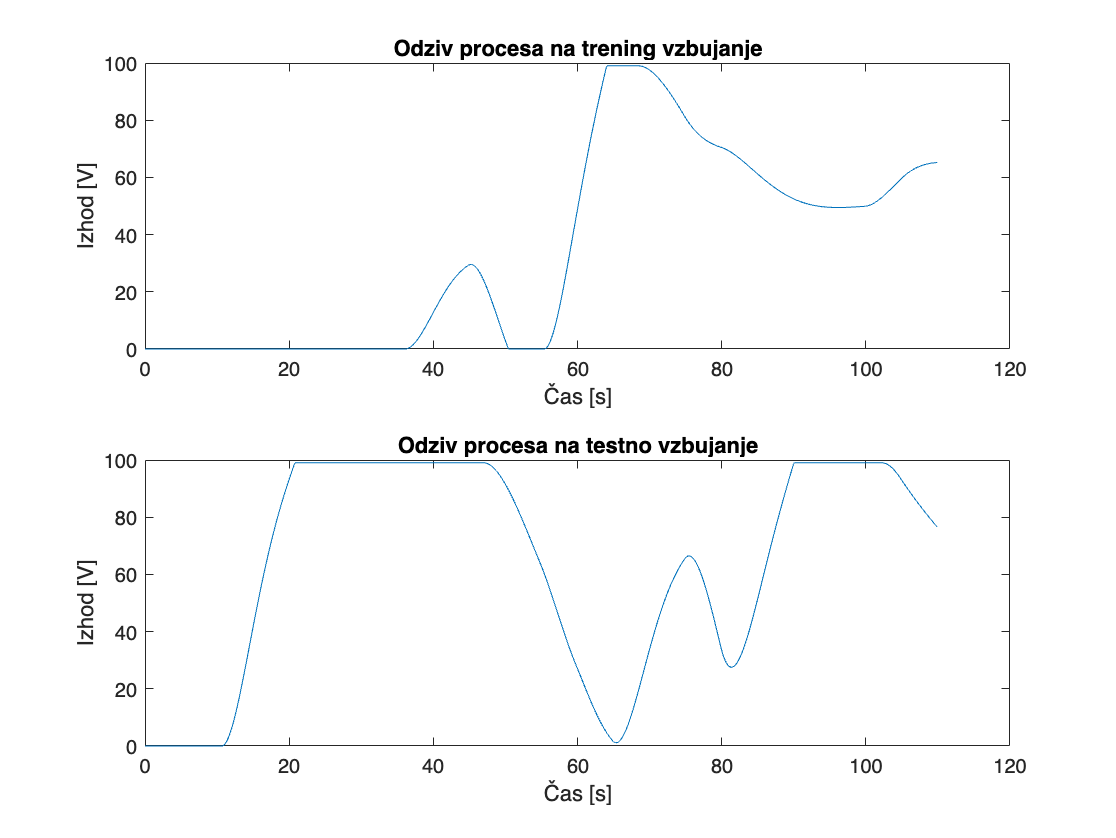


% Simulacija odziva sistema za treniranje in testiranje
y_train = simulate_helicrane(u_train, [0 0]);
y_test = simulate_helicrane(u_test, [0 0]);

% Risanje rezultatov simulacije
figure
subplot(2, 1, 1);
plot(t_train, y_train);
title("Odziv procesa na trening vzbujanje");
xlabel("Čas [s]");
ylabel("Izhod [V]");

subplot(2, 1, 2);
plot(t_test, y_test);
title("Odziv procesa na testno vzbujanje");
xlabel("Čas [s]");
ylabel("Izhod [V]");


% Preverjanje dolžine vektorjev u_train in y_train
if length(u_train) > 2 && length(y_train) > 2
    % Priprava vhodnih in izhodnih podatkov za učenje
    X_train_podatki = [u_train(2:end-1), u_train(1:end-2), -y_train(2:end-1), -y_train(1:end-2)];
    Y_train_podatki = y_train(3:end);

    % Premešanje podatkov za učenje
    perm_indeksi = randperm(size(X_train_podatki, 1));
    X_train_premesani = X_train_podatki(perm_indeksi, :);
    Y_train_premesani = Y_train_podatki(perm_indeksi, :);

    % Priprava vhodnih in izhodnih podatkov za testiranje
    X_test_podatki = [u_test(2:end-1), u_test(1:end-2), -y_test(2:end-1), -y_test(1:end-2)];
    Y_test_podatki = y_test(3:end);

    % Simulacija helicrana brez uporabe funkcije
    % Inicializacija stanja
    zacetno_stanje = [0, 0];

    % Dolžina vhoda
    N = length(u_train); % Tu mora biti dolžina u_train

    % Inicializacija izhoda
    izhodi = zeros(N, 1);

    % Glavna zanka za simulacijo
    for i = 1:N
        % Klic funkcije helicrane
        [fi_, fip_] = helicrane(u_train(i), zacetno_stanje);

        % Posodobitev stanja
        zacetno_stanje = [fip_, fi_];

        % Shranjevanje izhoda
        izhodi(i) = fi_;
    end

    % Prikaz končnih izhodov (izhodi)
    disp(izhodi);
else
    disp('Napaka: u_train ali y_train nimata dovolj elementov.');
end

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0

## nevronska mreža

net = feedforwardnet([15, 12, 10]);
net.layers{1}.transferFcn = 'tansig';
net.layers{2}.transferFcn = 'tansig';
net.layers{3}.transferFcn = 'poslin';
net.trainParam.showWindow = false;
net.trainParam.goal = 2e-6;
[net, ~] = train(net, X_train_podatki', Y_train_podatki');

% Napovedovanje na trening množici
Y_pred_train = net(X_train_podatki');

% Napovedovanje na testni množici
Y_pred_test = net(X_test_podatki');

% Risanje rezultatov
figure;
subplot(2, 1, 1);
plot(Y_train_podatki);
title("Modeliranje trening množice z NN");
hold on;
plot(Y_pred_train);
xlabel("Vzorec");
ylabel("Odziv [V]");

subplot(2, 1, 2);
plot(Y_test_podatki);
title("Modeliranje testne množice z NN");
hold on;
plot(Y_pred_test);
xlabel("Vzorec");
ylabel("Odziv [V]");


## Takagi Sugeno model

% 1) Priprava vhodnih podatkov (X_train) in izhodnih podatkov (Y_train)
X_train_podatki = [u_train(2:end-1), u_train(1:end-2), -y_train(2:end-1), -y_train(1:end-2)];
Y_train_podatki = y_train(3:end);

% 2) pridobivanje centrov lokalnih funkcij s FCM
% Normalizacija vhodnih podatkov
%X_train_podatki = normalize(X_train_podatki);
%Y_train_podatki = normalize(Y_train_podatki);
X_test_podatki = normalize(X_test_podatki);

R = 11; % Število pravilsizesize
[centers, U] = fcm(X_train_podatki, R);

Iteration count = 1, obj. fcn = 312120
Iteration count = 2, obj. fcn = 232978
Iteration count = 3, obj. fcn = 218869
Iteration count = 4, obj. fcn = 159270
Iteration count = 5, obj. fcn = 68618.6
Iteration count = 6, obj. fcn = 29753.9
Iteration count = 7, obj. fcn = 15817.3
Iteration count = 8, obj. fcn = 9588.38
Iteration count = 9, obj. fcn = 6877.2
Iteration count = 10, obj. fcn = 5729.11
Iteration count = 11, obj. fcn = 5356.42
Iteration count = 12, obj. fcn = 5051.97
Iteration count = 13, obj. fcn = 4853.74
Iteration count = 14, obj. fcn = 4749.27
Iteration count = 15, obj. fcn = 4685.27
Iteration count = 16, obj. fcn = 4642.99
Iteration count = 17, obj. fcn = 4613.66
Iteration count = 18, obj. fcn = 4592.6
Iteration count = 19, obj. fcn = 4577.1
Iteration count = 20, obj. fcn = 4565.51
Iteration count = 21, obj. fcn = 4556.72
Iteration count = 22, obj. fcn = 4550.01
Iteration count = 23, obj. fcn = 4544.85
Iteration count = 24, obj. fcn = 4540.86
Iteration count = 25, obj. fcn =

C = centers; % Centri funkcij pripadnosti

% 3) Pripadnost funckije (O), uteži (W), pragovi (b)
O = ones(R, 1) * std(X_train_podatki); % Inicializacija širine funkcij pripadnosti
% Za vsako vvhodno spremenljivko računamo std -> 1 x n
W = rand(R, size(X_train_podatki, 2)) * 2 - 1; % Naključna inicializacija uteži od -1 do 1
b = rand(R, 1) * 2 - 1; % Naključna inicializacija pragov


% 4) trening TS modela
alpha = 0.0005; % Hitrost učenja, 0.0000001 
epochs = 1000; % Število epoh za treniranje
[C, O, W, b, e] = TS_train(C, O, W, b, X_train_podatki', Y_train_podatki', alpha, epochs);

Epoka 100: Povprečna napaka: 217609913626692780225174068919196789751291763276213306875763680662230700783462695125498666014041797891726146514745149962000640212662403881640901002882187264.000000
Epoka 200: Povprečna napaka: 217609913626692780225174068919196789751291763276213306875763680662230700783462695125498666014041797891726146514745149962000640212662403881640901002882187264.000000
Epoka 300: Povprečna napaka: 217609913626692780225174068919196789751291763276213306875763680662230700783462695125498666014041797891726146514745149962000640212662403881640901002882187264.000000
Epoka 400: Povprečna napaka: 217609913626692780225174068919196789751291763276213306875763680662230700783462695125498666014041797891726146514745149962000640212662403881640901002882187264.000000
Epoka 500: Povprečna napaka: 217609913626692780225174068919196789751291763276213306875763680662230700783462695125498666014041797891726146514745149962000640212662403881640901002882187264.000000
Epoka 600: Povprečna napaka: 217609

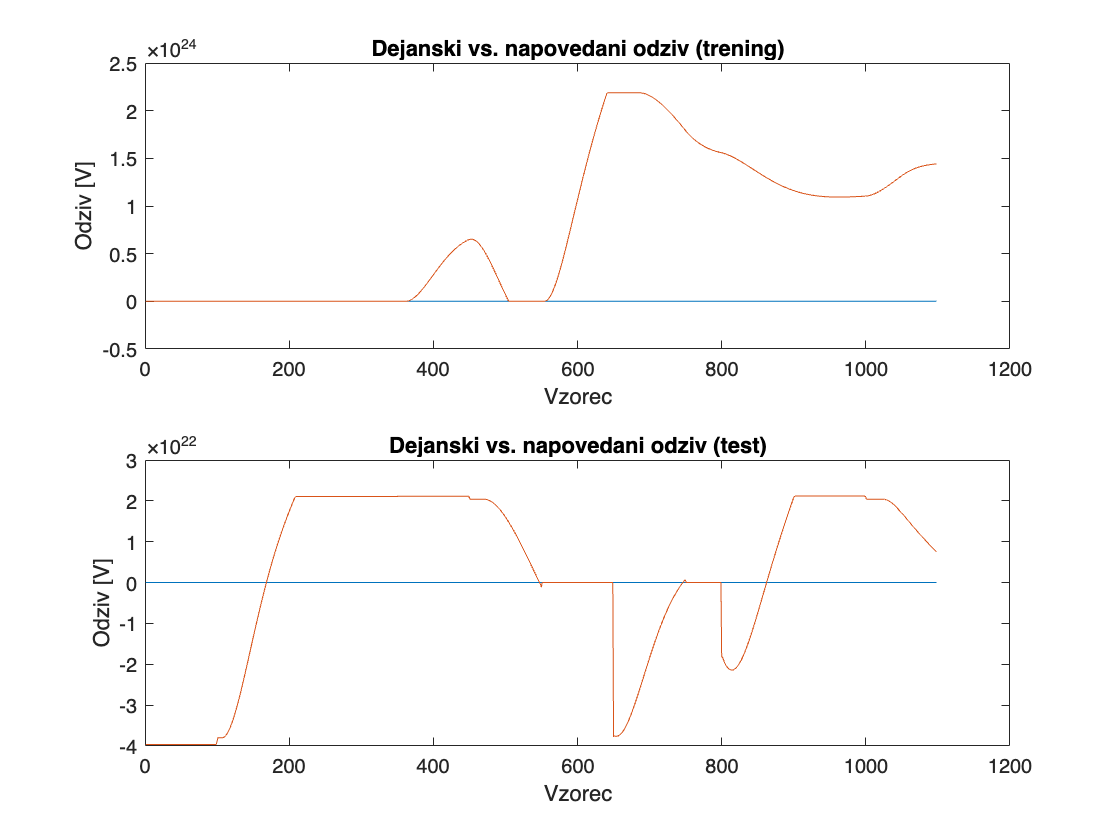

% 5) testiranje na testnih podatkih
Y_pred_train = TS_eval(C, O, W, b, X_train_podatki');
Y_pred_test = TS_eval(C, O, W, b, X_test_podatki');

% Risanje rezultatov
figure;
subplot(2, 1, 1);
plot(Y_train_podatki);
hold on;
plot(Y_pred_train);
title('Dejanski vs. napovedani odziv (trening)');
xlabel('Vzorec');
ylabel('Odziv [V]');

subplot(2, 1, 2);
plot(Y_test_podatki);
hold on;
plot(Y_pred_test);
title('Dejanski vs. napovedani odziv (test)');
xlabel('Vzorec');
ylabel('Odziv [V]');

function [C, O, W, b, e_avg] = TS_train(C, O, W, b, X, Y, alpha, epochs)
    [R, n] = size(C);
    
    for epoch = 1:epochs
        e_sum = 0;
        for i = 1:size(X, 2)
            x = X(:, i);
            y_true = Y(i);
            
            mu = exp(-0.5 * sum((x' - C).^2 ./ (O.^2), 2));
            mu_sum = sum(mu);
            
            if mu_sum > 0
                mu = mu / (mu_sum + 1e-9); % Dodajanje konstante za stabilnost
            end
            
            y_pred = sum(mu .* (W * x + b));
            e = y_true - y_pred;
            e_sum = e_sum + e^2;
            
            % Posodobitev parametrov
            dmu_dC = (x' - C) ./ (O.^2) .* mu;
            dmu_dO = ((x' - C).^2) ./ (O.^3) .* mu;
            dy_dC = dmu_dC .* (W * x + b - sum(mu .* (W * x + b))) ./ (mu_sum^2 + 1e-9);
            dy_dO = dmu_dO .* (W * x + b - sum(mu .* (W * x + b))) ./ (mu_sum^2 + 1e-9);
            dy_db = mu;
            dy_dW = mu * x';
            
            C = C + alpha * (-2 * e * dy_dC);
            O = O + alpha * (-2 * e * dy_dO);
            b = b + alpha * (-2 * e * dy_db);
            W = W + alpha * (-2 * e * dy_dW);
        end
        
        e_avg = e_sum / size(X, 2);
        
        if mod(epoch, 100) == 0
            fprintf("Epoka %d: Povprečna napaka: %f\n", epoch, e_avg);
        end
    end
    
    fprintf("Končna povprečna napaka: %f\n", e_avg);
end


function Y_pred = TS_eval(C, O, W, b, X)
    % C - centri (R x n)
    % O - širine funkcij pripadnosti (R x n)
    % W - uteži (R x n)
    % b - pristranskosti (R x 1)
    % X - vhodni podatki (n x m)
    % Y_pred - napovedani izhodni podatki (1 x m)
    
    % Število pravil (R) in število vhodov (n)
    [R, n] = size(C);
    
    % Število podatkovnih točk
    m = size(X, 2);
    
    % Inicializacija izhodnega vektorja
    Y_pred = zeros(1, m);
    
    % Glavna zanka za napovedovanje
    for i = 1:m
        x = X(:, i);  % Trenutni vhod (n x 1)
        
        % Izračun pripadnosti za vsak center
        mu = exp(-0.5 * sum((x' - C).^2 ./ (O.^2), 2));  % Pripadnost (R x 1)
        mu_sum = sum(mu);  % Vsota pripadnosti
        
        if mu_sum > 0
            mu = mu / mu_sum;  % Normalizacija pripadnosti
        end
        
        % Napovedana vrednost
        Y_pred(i) = sum(mu .* (W * x + b));  % Napovedana vrednost (skalar)
    end
end

